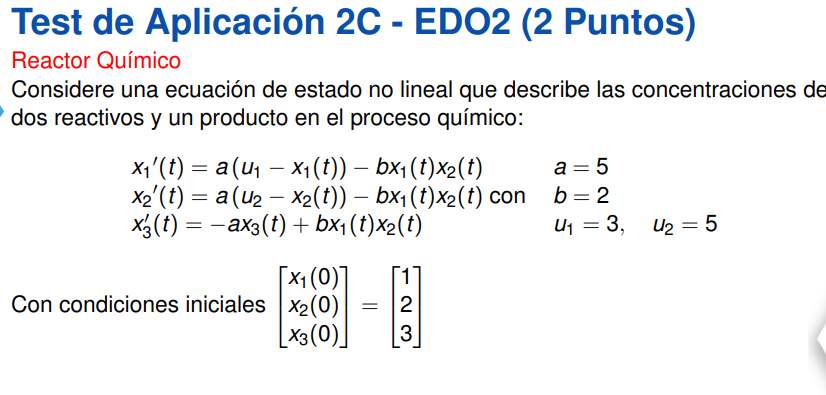

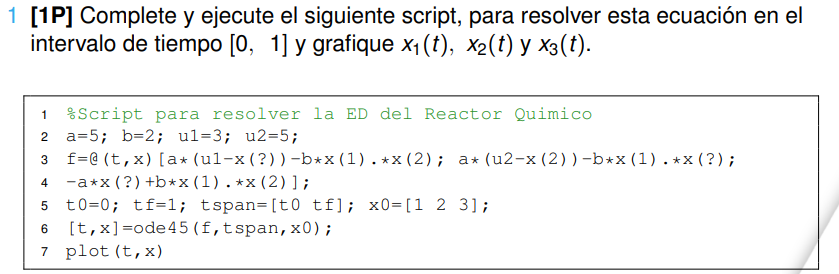

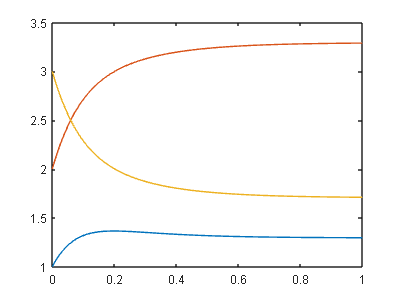

a=5; b=2; u1=3; u2=5;
f=@(t,x) [a*(u1-x(1))-b*x(1).*x(2); a*(u2-x(2))-b*x(1).*x(2); -a*x(3)+b*x(1).*x(2)];
t0=0; tf=1; tspan=[t0 tf]; x0=[ 1 2 3];
[t,x] = ode45(f,tspan,x0);
plot(t,x)

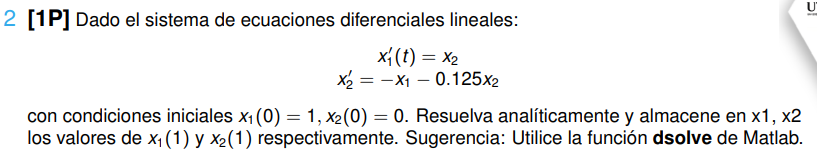

syms x1(t) x2(t)
eqn =[ diff(x1,t)==x2  , diff(x2,t)==-x1-0.125*x2]

$$eqn(t) = \left(\begin{array}{cc} \frac{\partial }{\partial t}x_{1}\left(t\right)=x_{2}\left(t\right) & \frac{\partial }{\partial t}x_{2}\left(t\right)=-x_{1}\left(t\right)-\frac{x_{2}\left(t\right)}{8} \end{array}\right)$$

cond = [x1(0)==1, x2(0)==0]

$$cond = \left(\begin{array}{cc} x_{1}\left(0\right)=1 & x_{2}\left(0\right)=0 \end{array}\right)$$

S= dsolve(eqn,cond);
sol_x1=matlabFunction(S.x1);

sol_x2= matlabFunction(S.x2);

x1 = sol_x1(1)

x1 =    0.558551602703109


x2 = sol_x2(1)

x2 =   -0.791041527894495
